# Kalman filter

clear all

Basic Kalman filter code from A. Desbiens (July 2021) adapted to produce benchmark simulation data for use in unit testing.

## Simulation settings

Np=100; % number of points
Ts=3; % sampling period
t=(0:Np-1)*Ts; % time vector

## System

G=tf(2,conv([10 1],[15 1])); % plant
G=ss(c2d(G,Ts,'zoh'));
A=G.a; 
B=G.b;
C=G.c;
D=G.d;
n=length(A); % number of states
ny=size(C,1); % number of outputs
Qp=diag([0.3; 0.2]); % covariance - process noise
Rp=0.4; % variance - measurement noise

## Kalman covariance matrices

Q=diag([0.1; 0.1]);
R=0.5;
N=zeros(n,ny);

## Kalman model

Gkf=eye(n);
Hkf=zeros(ny,n);
Gmodel=ss(A,[B Gkf],C,[D Hkf],Ts);

## Kalman filter, steady-state, prediction form ('delayed')

[KalmanFilter, K, P]=kalman(Gmodel,Q,R,N,'delayed')

KalmanFilter =
 
  A = 
            x1_e     x2_e
   x1_e    1.402  -0.7397
   x2_e   0.8462  -0.1302
 
  B = 
             u1      y1
   x1_e    0.25  0.7727
   x2_e       0  0.7557
 
  C = 
           x1_e    x2_e
   y1_e  0.2036  0.1723
   x1_e       1       0
   x2_e       0       1
 
  D = 
         u1  y1
   y1_e   0   0
   x1_e   0   0
   x2_e   0   0
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
    StateEstimate       2,3   
                              
Sample time: 3 seconds
Discrete-time state-space model.



K =     0.7727
    0.7557


P =     1.5098    1.2170
    1.2170    1.2191


## Check steady-state P, K using the Kalman equations

P2 = 1e5*eye(n);
for i = 1:25
    K2 = A*P2*C'*inv(C*P2*C' + R);
    P2 = A*(P2 - P2*C'*inv(C*P2*C' + R)*C*P2)*A' + Q;
end
assert(all(abs(K - K2) < 1e-6, [1 2]))
assert(all(abs(P - P2) < 1e-6, [1 2]))

## Intial states, input, process and measurement noises

u0=1; % initial value of u
x0=inv(eye(length(A))-A)*B*u0; % initial states

u=[zeros(10,1); ones(Np-10,1)]; % process input for the whole simulation

rng(0)  % seed random number generator
v=sqrt(Rp)*randn(Np,1); % measurement noise for the whole simulation
w=sqrt(Qp)*randn(2,Np); % proces noise for the whole simulation
% or for a non-diagonal covariance matrix:
% L = chol(Qp,'lower'); 
% w = (L*randn(length(Qp),Np))';


## Simulation with Simulink

open('Kalman_Filter_sim_model.slx');
sim('Kalman_Filter_sim_model.slx');

## Simulation with a loop

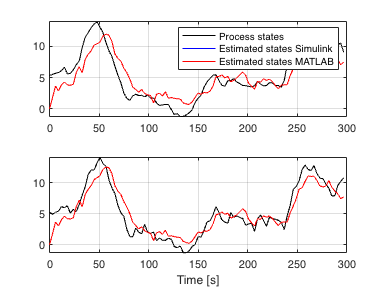

% kalman1: with KalmanFilter calculated at line 21
% kalman2: with K calculated at line 27
x=x0; % initial states of the process
xkalman=zeros(length(KalmanFilter.A),1); % initial estimated states - kalman1
xNprocess=zeros(length(x),Np); % matrix to collect process states
xNkalman=xNprocess; % matrix to collect estimated states
for i=1:Np

    y = C*x+v(i); % process output
    xNprocess(:,i) = x; % collect data
    xNkalman(:,i) = xkalman; % collect data
    x = A*x+B*u(i)+w(:,i); % process states udpdate
    xkalman = KalmanFilter.A*xkalman + KalmanFilter.B*[u(i); y]; % Kalman filter
    
end
% plot results
figure(1);
subplot(211);
plot(t,xNprocess(1,:),'k',t,xNkalman(1,:),'b',t,xhat_Simulink.Data(:,1)','r')
legend('Process states','Estimated states Simulink','Estimated states MATLAB')
grid on
subplot(212);
plot(t,xNprocess(2,:),'k',t,xNkalman(2,:),'b',t,xhat_Simulink.Data(:,2)','r')
xlabel('Time [s]');
grid on

## Compare simulation results

% Output from Matlab simulation
sim_results1 = [
    table(t', 'VariableNames', {'t'}) ...
    array2table(xNprocess', 'VariableNames', {'xNprocess_1', 'xNprocess_2'}) ...
    array2table(xNkalman', 'VariableNames', {'xNkalman_1', 'xNkalman_2'}) ...
];
head(sim_results1)

ans = 8×5 table
    t     xNprocess_1    xNprocess_2    xNkalman_1    xNkalman_2
    __    ___________    ___________    __________    __________

     0      5.3212         5.3212              0             0  
     3      5.5315         4.9241         1.8083        1.7684  
     6      5.6949          5.288         3.6496        3.6685  
     9      5.8404         5.4264            2.9        3.0954  
    12      6.0854          6.171         3.8395        4.0679  
    15      6.6852         5.9986         4.3096        4.6112  
    18      5.6164         6.3098         3.8435        4.2307  
    21      5.6739         5.1369         3.7719        4.1797  


% Output from Simulink model
sim_results2 = [
    array2table(x_Simulink.Time, 'VariableNames', {'t'}) ...
    array2table(x_Simulink.Data, 'VariableNames', {'x1', 'x2'}) ...
    array2table(xhat_Simulink.Data, 'VariableNames', {'x1_est', 'x2_est'}) ...
];
head(sim_results2)

ans = 8×5 table
    t       x1        x2      x1_est    x2_est
    __    ______    ______    ______    ______

     0    5.3212    5.3212         0         0
     3    5.5315    4.9241    1.8083    1.7684
     6    5.6949     5.288    3.6496    3.6685
     9    5.8404    5.4264       2.9    3.0954
    12    6.0854     6.171    3.8395    4.0679
    15    6.6852    5.9986    4.3096    4.6112
    18    5.6164    6.3098    3.8435    4.2307
    21    5.6739    5.1369    3.7719    4.1797


% Check results are same
assert(isequal(round(sim_results1.Variables,4), ...
    round(sim_results2.Variables,4)))

## Save simulation results for unit testing

filename = 'Kalman_Filter_sim_benchmark.csv';
writetable(sim_results1, fullfile('results', filename))